str = input('Type a nonlinear equation in x: ','s');
f= inline(str);
Method=input('Choose the method you want to use :\n1: Bisection\n2: False-position\n3: Fixed-Point\n4: Newton-Raphson\n5: Secant\n');


Bisection

if Method == 1,
  x1=input('Enter the initial bracket value\n');
  x2=input('Enter the final bracket value\n');

  if x1>=x2,
    fprintf('Please enter proper bracket\n');
    return;
  end;
  MaxIt=input('Type the maximum iterations you want for this method:\n');

  MaxErr=input('Type the maximum relative approximate err you want for this method:\n')

  xran = (x1-(x2-x1)):0.1:(x2+(x2-x1));
  figure;
  for val=1:1:size(xran,2)
    y(val) = f(xran(val));
  end;
  plot(xran,y)
  xlabel('x');
  ylabel('f(x)');
  y1=f(x1);
  y2=f(x2);
  err(1)=100;
  iter=0;
  yf=1;
   lastxf=111;
  flag=0;
  while (flag==0 )|| ((err(iter)>MaxErr) && (iter<MaxIt) && (yf~=0))
    flag=1;
    xf=(x1+x2)/2;
    yf=f(xf);
    if (yf*y1<0)
      y2=yf;
      x2=xf;
      err(iter+1)=abs((lastxf-xf)*100/xf);
      lastxf=xf;
      iter= iter + 1;
    
    else
      x1=xf;
      y1=yf;
      err(iter+1)=abs((lastxf-xf)*100/xf);
      lastxf=xf;
      iter= iter + 1;
    end;
    
  end;  
  fprintf('The root of the equation: %f', xf);
  iterations = 2:1:iter;
  err =err(1,2:iter);
  figure;
  plot(iterations, err)
  xlabel('Number of iterations');
  ylabel('Relative approximate err');
  
end;

False-Position

if Method == 2,
  x1=input('Enter the lower bracket for the root\n');

  x2=input('Enter the upper bracket for the root\n');

  
  if x1>=x2,
    fprintf('Please enter proper bracket\n');
    return;
  end;
  MaxIt=input('Type the maximum iterations you want for this method:\n');

  MaxErr = input('Type the maximum relative approximate err you want for this method:\n')

  xran = (x1-(x2-x1)):0.1:(x2+(x2-x1));
  figure;
  for val=1:1:size(xran,2)
    y(val) = f(xran(val));
  end;
  plot(xran,y)
  xlabel('x');
  ylabel('f(x)');
  y1=f(x1);
  y2=f(x2);
  err(1)=100;
  iter=0;
  yf=1;
  lastxf=111;
  flag=0;
  while (flag==0 )|| ((err(iter)>MaxErr) && (iter<MaxIt) && (yf~=0))
    flag=1;
    xf=x2 - y2*((x2-x1)/(y2-y1));
    yf=f(xf);
    if (yf*y1<0)
      y2=yf;
      x2=xf;
      err(iter+1)=abs((lastxf-xf)*100/xf);
      lastxf=xf;
      iter= iter + 1;
    
    else
      x1=xf;
      y1=yf;
      err(iter+1)=abs((lastxf-xf)*100/xf);
      lastxf=xf;
      iter= iter + 1;
    end;
    
  end;  
  fprintf('The root of the equation: %f', xf);
  iterations = 2:1:iter;
  err =err(1,2:iter);
  figure;
  plot(iterations, err)
  xlabel('Number of iterations');
  ylabel('Relative approximate err');
  
end;

Fixed-Point


if Method == 3,
  phiInput = input('Type phi(x):','s');
  phi = inline(phiInput);
  x1 = input('Type the initial guess\n');

  MaxIt=input('Type the maximum iterations you want for this method:\n');

  MaxErr = input('Type the maximum relative approximate err you want for this method:\n')

  if x1>=0
    xran = (-x1-10):0.1:(2*x1+10);
  else
    xran = (-x1+10):-0.1:(2*x1-10);
  end;
  figure;
  for val=1:1:size(xran,2)
    y(val) = f(xran(val));
  end;
  plot(xran,y)
  xlabel('x');
  ylabel('f(x)');
  err(1)=200;
  iter=0;
  flag=0;
  xf=x1;
  lastxf =x1;
  while (flag==0 )|| ((err(iter)>MaxErr) && (iter<MaxIt))
    flag=1;
    yf=phi(xf);
    xf=yf;
    err(iter+1)=abs((lastxf-xf)*100/xf);
    lastxf=xf;
    iter= iter + 1;
  end;  
  fprintf('The root of the equation: %f', xf);
  iterations = 1:1:iter-1;
  err =err(1,1:iter-1);
  figure;
  plot(iterations, err)
  xlabel('Number of iterations');
  ylabel('Relative approximate err');
  
end;


Newton-Raphson

if Method == 4,
  phiInput = input('Enter derivative of f(x):','s');
  phi = inline(phiInput);
  x1 = input('Type the initial guess\n');

  
  MaxIt=input('Type the maximum iterations you want for this method:\n');

  MaxErr = input('Type the maximum relative approximate err you want for this method:\n')

  if x1>=0
    xran = (-x1-5):0.1:(2*x1+5);
  else
    xran = (-x1+5):-0.1:(2*x1-5);
  end;
  figure;
  for val=1:1:size(xran,2)
    y(val) = f(xran(val));
  end;
  plot(xran,y)
  xlabel('x');
  ylabel('f(x)');
  err(1)=100;
  iter=0;
  flag=0;
  xf=x1;
  lastxf =x1;
  while (flag==0 )|| ((err(iter)>MaxErr) && (iter<MaxIt))
    flag=1;
    yf=f(xf);
    xf=xf - (yf/phi(xf));
    err(iter+1)=abs((lastxf-xf)*100/xf);
    lastxf=xf;
    iter= iter + 1;
  end;  
  fprintf('The root of the equation: %f', xf);
  iterations = 1:1:iter-1;
  err =err(1,1:iter-1);
  figure;
  plot(iterations, err)
  xlabel('Number of iterations');
  ylabel('Relative approximate err');
  
end;

Secant

MaxErr = 0.0500

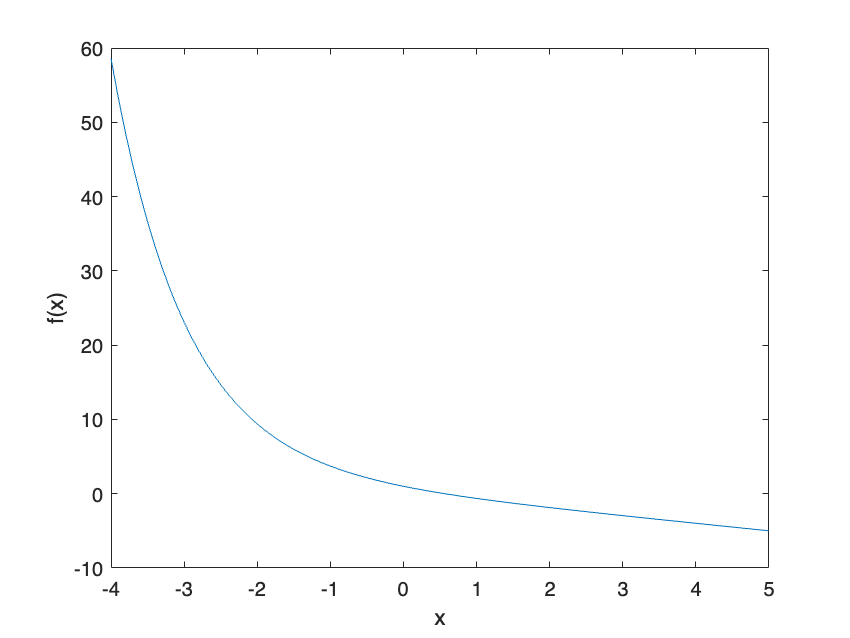

The root of the equation: 0.567126

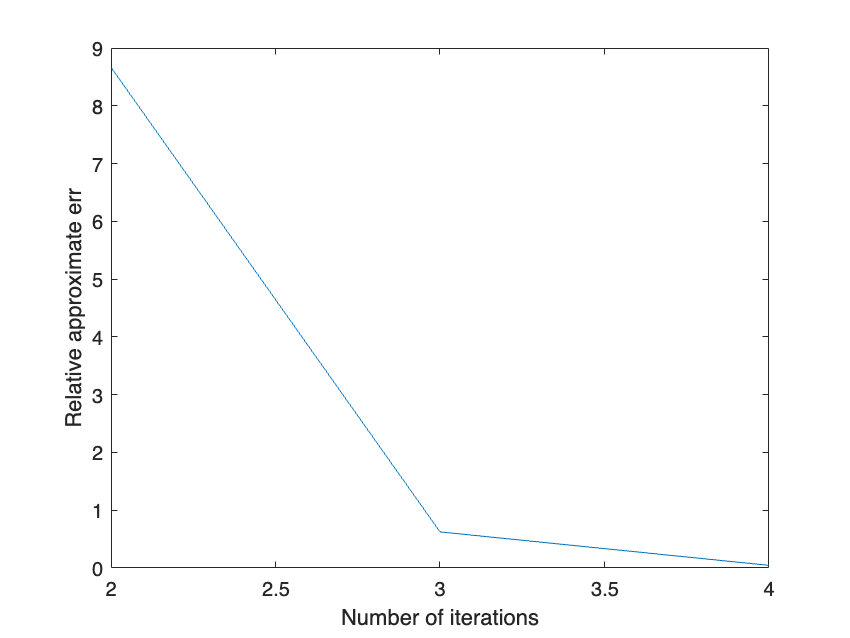

if Method == 5,
  x1 = input('Enter the initial bracket value\n');

  x2 = input('Enter the final bracket value\n');

  MaxIt=input('Type the maximum iterations you want for this method:\n');

  MaxErr = input('Type the maximum relative approximate err you want for this method:\n')

  xran = (x1-4*(x2-x1)):0.1:(x2+4*(x2-x1));
  figure;
  for val=1:1:size(xran,2)
    y(val) = f(xran(val));
  end;
  plot(xran,y)
  xlabel('x');
  ylabel('f(x)');
  err(1)=100;
  iter=0;
  flag=0;
  y1=f(x1);
  y2=f(x2);
  xf=x1;
  lastxf =x1;
  while (flag==0 )|| ((err(iter)>MaxErr) && (iter<MaxIt))
    flag=1;
    xf=x2 - y2*((x2-x1)/(y2-y1));
    yf=f(xf);
    if y1>y2
      y1=yf;
      x1=xf;
    else
      y2=yf;
      x2=xf;
    end;
    
    err(iter+1)=abs((lastxf-xf)*100/xf);
    lastxf=xf;
    iter= iter + 1;
  end;  
  fprintf('The root of the equation: %f', xf);
  iterations = 2:1:iter;
  err =err(1,2:iter);
  figure;
  plot(iterations, err)
  xlabel('Number of iterations');
  ylabel('Relative approximate err');
  
end;

clear